**Data**

x = [10 20 30 40 50 60 70 80]';

y = [25 70 380 550 610 1220 830 1450]';

**Plot data**

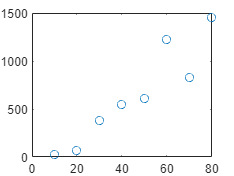


plot(x,y,'o')

**Create Z matrix**


z = [ones(8,1) x x.^2]

z =            1          10         100
           1          20         400
           1          30         900
           1          40        1600
           1          50        2500
           1          60        3600
           1          70        4900
           1          80        6400


**Solve for unknown parameters  a  **

a = (z'*z) \ (z'*y)

a =  -178.4821
   16.1220
    0.0372


**Plot data and the best fitted curve**

xx = 10 : 0.5 : 80

xx =    10.0000   10.5000   11.0000   11.5000   12.0000   12.5000   13.0000   13.5000   14.0000   14.5000   15.0000   15.5000   16.0000   16.5000   17.0000   17.5000   18.0000   18.5000   19.0000   19.5000   20.0000   20.5000   21.0000   21.5000   22.0000   22.5000   23.0000   23.5000   24.0000   24.5000   25.0000   25.5000   26.0000   26.5000   27.0000   27.5000   28.0000   28.5000   29.0000   29.5000   30.0000   30.5000   31.0000   31.5000   32.0000   32.5000   33.0000   33.5000   34.0000   34.5000



yy = a(1) + a(2).*xx + a(3).*xx.*xx

yy = 1.0e+03 *

   -0.0135   -0.0051    0.0034    0.0118    0.0203    0.0289    0.0374    0.0459    0.0545    0.0631    0.0717    0.0803    0.0890    0.0977    0.1063    0.1150    0.1238    0.1325    0.1413    0.1500    0.1588    0.1677    0.1765    0.1853    0.1942    0.2031    0.2120    0.2209    0.2299    0.2388    0.2478    0.2568    0.2658    0.2749    0.2839    0.2930    0.3021    0.3112    0.3203    0.3295    0.3387    0.3478    0.3571    0.3663    0.3755    0.3848    0.3941    0.4034    0.4127    0.4220


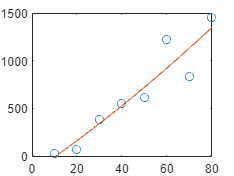


plot(x,y,'o',xx,yy,'-')

**Compute  Sr  (the sum of the squares of the residuals between the best-fit curve and the data)**

Sr = sum((y-z*a).^2)

Sr = 2.1379e+05

**Compute  St   (the sum of the squares of the residuals between the data points and the mean)**

St = sum((y-mean(y)).^2)

St = 1.8083e+06

**Compute  r2  (the coefficient of determination)**

r2 = 1 - Sr/St

r2 = 0.8818

**Compute  syx  (the standard error of the estimate)  **


syx = sqrt(Sr/(length(x)-length(a)))

syx = 206.7815

**Predict the value of y for the given x**

xtest = 22;
predict_y = a(1) + a(2).*xtest + a(3).*xtest.*xtest

predict_y = 194.2083